# ECE 455 Robot Calculations

%___Get Transformation Matrix, Copied from 3____
clear

syms theta1 theta2 theta3 theta4 theta5 theta6
syms L1 L2 L3 L4 L5 L6

syms P_x P_y P_z

% substitutions
theta4 = 0;
theta5 = 0;
theta6 = 0;
L1 = 89.2*10^-3;    % meters
L2 = 109.3*10^-3;
L3 = 425*10^-3;
L4 = 392*10^-3;
L5 = 94.75*10^-3;
L6 = 82.5*10^-3;

% Transformation Matrices

% Translate up L1
T_01 = [1   0   0   0;
        0   1   0   0;
        0   0   1   L1;
        0   0   0   1];

% Rotate Z theta1
T_12 = [cos(theta1)   -sin(theta1)   0   0;
        sin(theta1)   cos(theta1)    0   0;
        0   0   1   0;
        0   0   0   1];

% Rotate Y theta2
T_23 = [cos(theta2)   0   sin(theta2)   0;
        0   1   0   0;
        -sin(theta2)   0   cos(theta2)   0;
        0   0   0   1];

% Translate Z L3
T_34 = [1   0   0   0;
        0   1   0   0;
        0   0   1   L3;
        0   0   0   1];

% Rotate Y theta3
T_45 = [cos(theta3)   0   sin(theta3)   0;
        0   1   0   0;
        -sin(theta3)   0   cos(theta3)   0;
        0   0   0   1];

% Translate Z L4, Y -L2
T_56 = [1   0   0   0;
        0   1   0   -L2;
        0   0   1   L4;
        0   0   0   1];

% Rotate Y theta4
T_67 = [cos(theta4)   0   sin(theta4)   0;
        0   1   0   0;
        -sin(theta4)   0   cos(theta4)   0;
        0   0   0   1];

% Translate Z L5
T_78 = [1   0   0   0;
        0   1   0   0;
        0   0   1   L5;
        0   0   0   1];

% Rotate Z theta5
T_89 = [cos(theta5)   -sin(theta5)   0   0;
        sin(theta5)   cos(theta5)    0   0;
        0   0   1   0;
        0   0   0   1];

% Translate Y -L6
T_9A = [1   0   0   0;
        0   1   0   -L6;
        0   0   1   0;
        0   0   0   1];

% Rotate Y theta6
T_AB = [cos(theta6)   0   sin(theta6)   0;
        0   1   0   0;
        -sin(theta6)   0   cos(theta6)   0;
        0   0   0   1];

format long

% Overall Transformation Matrix
T_04 = T_01*T_12*T_23*T_34;
T_06 = T_04*T_45*T_56;
T_08 = T_06*T_67*T_78;
T_0B = T_08*T_89*T_9A*T_AB;

% Start of Jacobian 
P_x = T_0B(1, 4)

$$P\_x = \frac{959\,\sin\left(\theta_{1}\right)}{5000}+\frac{17\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{40}+\frac{1947\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000}+\frac{1947\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{4000}$$

P_y = T_0B(2, 4)

$$P\_y = \frac{17\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{40}-\frac{959\,\cos\left(\theta_{1}\right)}{5000}+\frac{1947\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{4000}+\frac{1947\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{4000}$$

P_z = T_0B(3, 4)

$$P\_z = \frac{17\,\cos\left(\theta_{2}\right)}{40}+\frac{1947\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{4000}-\frac{1947\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000}+\frac{223}{2500}$$


% Jacobian Matrix theta1 - theta6
% Commented out to run faster
% Total_Jacobian = [diff(P_x,theta1) diff(P_x,theta2) diff(P_x,theta3) diff(P_x,theta4) diff(P_x,theta5) diff(P_x,theta6);
%             diff(P_y,theta1) diff(P_y,theta2) diff(P_y,theta3) diff(P_y,theta4) diff(P_y,theta5) diff(P_y,theta6);
%             diff(P_z,theta1) diff(P_z,theta2) diff(P_z,theta3) diff(P_z,theta4) diff(P_z,theta5) diff(P_z,theta6)];

% Jacobian Matrix 3x3 from theta1-theta3
J = [diff(P_x,theta1) diff(P_x,theta2) diff(P_x,theta3);
    diff(P_y,theta1) diff(P_y,theta2) diff(P_y,theta3);
    diff(P_z,theta1) diff(P_z,theta2) diff(P_z,theta3)]

$$J = \begin{array}{l} \left(\begin{array}{ccc} \frac{959\,\cos\left(\theta_{1}\right)}{5000}-\frac{17\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{40}-\frac{1947\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)}{4000}-\frac{1947\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{4000} & \frac{17\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{40}-\sigma_{1}+\sigma_{3} & \sigma_{3}-\sigma_{1}\\ \frac{959\,\sin\left(\theta_{1}\right)}{5000}+\frac{17\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{40}+\frac{1947\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000}+\frac{1947\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{4000} & \frac{17\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{40}-\sigma_{4}+\sigma_{2} & \sigma_{2}-\sigma_{4}\\ 0 & -\frac{17\,\sin\left(\theta_{2}\right)}{40}-\sigma_{6}-\sigma_{5} & -\sigma_{6}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1947\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000}\\ \sigma_{2}=\frac{1947\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)}{4000}\\ \sigma_{3}=\frac{1947\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)}{4000}\\ \sigma_{4}=\frac{1947\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000}\\ \sigma_{5}=\frac{1947\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)}{4000}\\ \sigma_{6}=\frac{1947\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{4000} \end{array}$$


% Calculate the determinant of J
determinant = det(J)

$$determinant = \frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{3}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{64443753\,{\cos\left(\theta_{2}\right)}^{3}\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{562683\,{\cos\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{6400000}+\frac{562683\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{562683\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{640000000}+\frac{562683\,{\cos\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{640000000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{640000000}+\frac{64443753\,{\cos\left(\theta_{2}\right)}^{2}\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{640000000}$$


Eqn_det = 0 == determinant

$$Eqn\_det = 0=\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{3}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{64443753\,{\cos\left(\theta_{2}\right)}^{3}\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{562683\,{\cos\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{6400000}+\frac{562683\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{562683\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{640000000}+\frac{562683\,{\cos\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{6400000}+\frac{64443753\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,{\sin\left(\theta_{2}\right)}^{3}\,\sin\left(\theta_{3}\right)}{640000000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,\cos\left(\theta_{2}\right)\,{\sin\left(\theta_{2}\right)}^{2}\,{\sin\left(\theta_{3}\right)}^{2}}{640000000}+\frac{64443753\,{\cos\left(\theta_{1}\right)}^{2}\,{\cos\left(\theta_{2}\right)}^{2}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{640000000}+\frac{64443753\,{\cos\left(\theta_{2}\right)}^{2}\,\cos\left(\theta_{3}\right)\,{\sin\left(\theta_{1}\right)}^{2}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)}{640000000}$$


mar = 1.01; % wiggle room
theta_range = [-pi*mar pi*mar; -pi*mar pi*mar; -pi*mar pi*mar];
% Solve for angles inverse kinematics

% Gather data for 200 different singularities
% calculating from random seed start points
clear sol
for k = 1:200
  result = vpasolve([Eqn_det], [theta1, theta2, theta3], theta_range, 'Random', true);
  sol(k,1) = double(result.theta1 * 180 / pi);
  sol(k,2) = double(result.theta2 * 180 / pi);
  sol(k,3) = double(result.theta3 * 180 / pi);
end
sol

sol = 	1.0e+00 *

 -127.2359 -160.3253 -180.0000
  122.8657   29.9448  -55.7837
  -86.3323 -117.6663 -112.9857
  -36.0287  -71.6482  127.6169
   83.5041    6.6235 -180.0000
  173.4578   97.7425  180.0000
 -146.5777  -64.6695  116.7794
 -148.7190  -48.0981   88.6297
  170.9757   25.4808  -47.5442
  -97.5653  -72.6941  129.1657


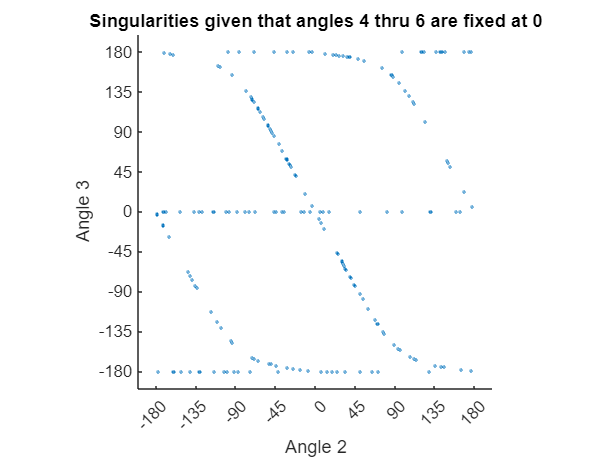

% Plot the singularities
scatter(sol(:,2),sol(:,3), 2)
xlabel('Angle 2');
ylabel('Angle 3');
xticks([-180 -135 -90 -45 0 45 90 135 180]);
yticks([-180 -135 -90 -45 0 45 90 135 180]);
pbaspect([1 1 1]); % aspect ratio
title('Singularities given that angles 4 thru 6 are fixed at 0')


% Has a pattern between angle 2 and angle 3
% Angle 1 is random